# LAB 10

## Name: Muhammad Asad Imran Rafique

## Student ID: 48065145

1a.

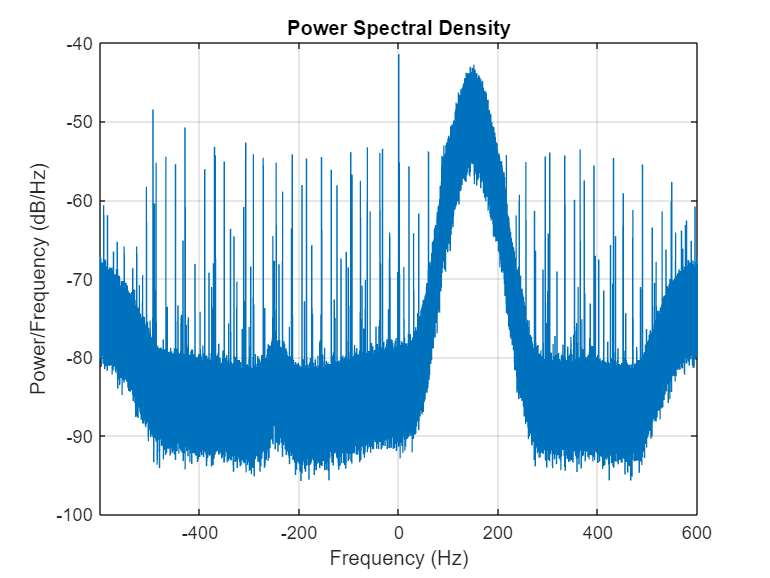


load('data_practical_W10.mat'); 

fs = 1.2e6;
Ts = 1/fs;
fc = 96.75e6; 
f_station = 96.9e6;

N = length(s); 
pwelch(s, [], [], [], fs, 'centered');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
title('Power Spectral Density');
grid on;

1b.

Kp = 1;
Ko = 1;
Bn = 50e3;
Zeta = 1;
fo = 100e3;

eta = (Bn * Ts)/(Zeta + 1/(4*Zeta))

eta = 0.0333

K1 = (4*Zeta*eta)/(Ko*Kp*(1+2*Zeta*eta + eta^2))

K1 = 0.1249

K2 = (4*eta^2)/(Ko*Kp*(1+2*Zeta*eta + eta^2))

K2 = 0.0042

1c.

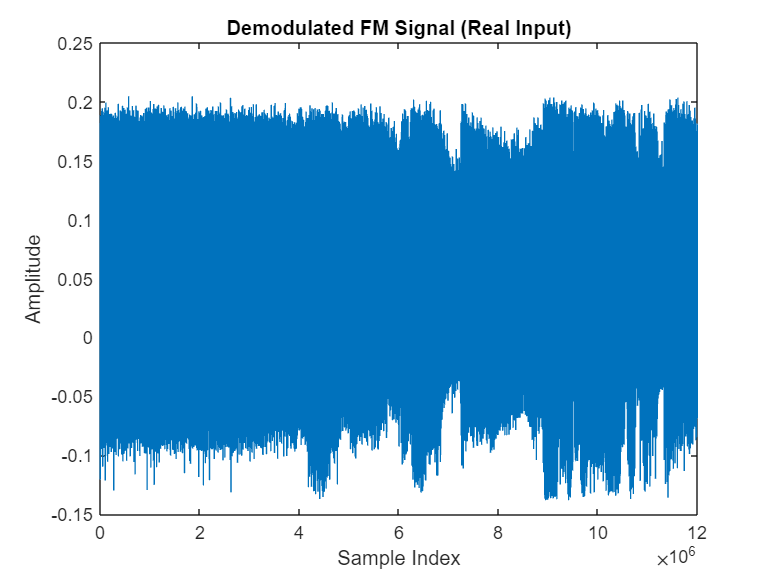

phi = zeros(size(s));
v1 = zeros(size(s));
v2 = zeros(size(s));
v3 = zeros(size(s));
c = zeros(size(s));

for n = 1:length(s)-1
    e = real(s(n)) * (- c(n));
    phi(n+1) = e*Kp;
    v1(n+1) = v1(n) + K2*phi(n);
    v2(n+1) = K1*phi(n) + v1(n); 
    v3(n+1) = v3(n) + Ko*(v2(n)+fo/fs);
    c(n+1) = sin(2*pi*v3(n)); 

end
figure;
plot(v2);
title('Demodulated FM Signal (Real Input)');
xlabel('Sample Index');
ylabel('Amplitude');

1d.

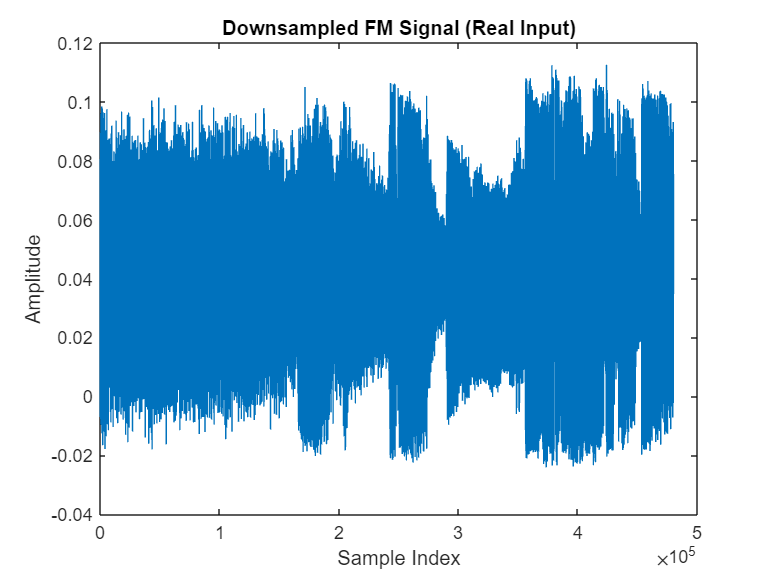

fs_down = 48e3;
v2_down = resample(v2, fs_down, fs);
soundsc(v2_down, fs_down);

figure;
plot(v2_down);
title('Downsampled FM Signal (Real Input)');
xlabel('Sample Index');
ylabel('Amplitude');

1e.

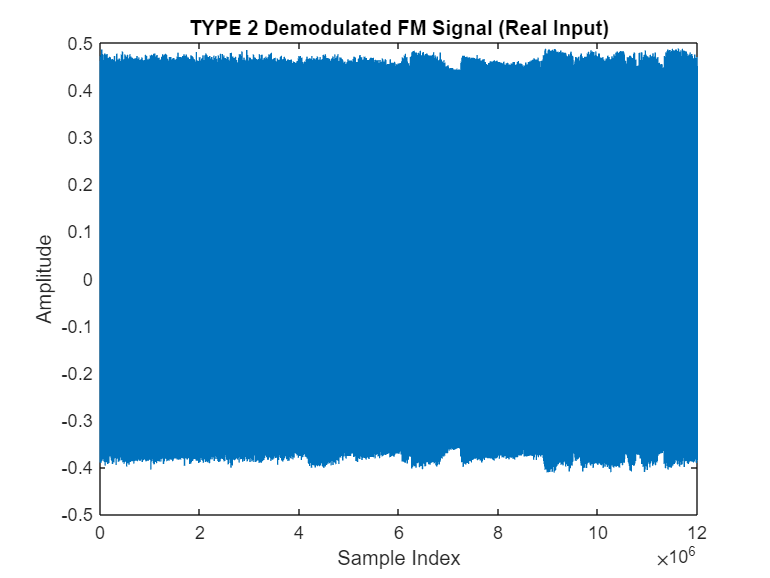

phi = zeros(size(s));
v1_type2 = zeros(size(s));
v2_type2 = zeros(size(s));
v3_type2 = zeros(size(s));
c = zeros(size(s));

for n = 1:length(s)-1
    e = angle(s(n) * c(n));
    phi(n+1) = e*Kp;
    v1_type2(n+1) = v1(n) + K2*phi(n);
    v2_type2(n+1) = K1*phi(n) + v1(n); 
    v3_type2(n+1) = v3(n) + Ko*(v2(n)+2*pi*fo/fs);
    c(n+1) = exp(-1j*v3(n));

end
figure;
plot(v2_type2);
title('TYPE 2 Demodulated FM Signal (Real Input)');
xlabel('Sample Index');
ylabel('Amplitude');

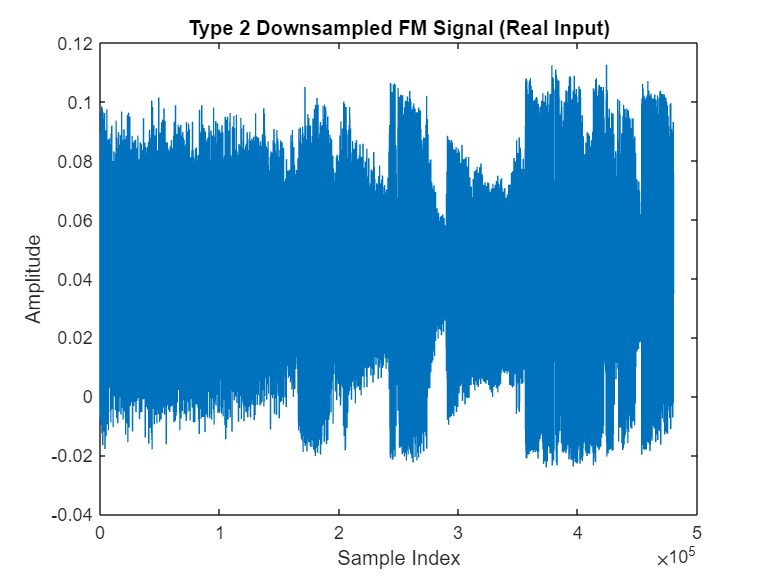


v2_down_type2 = resample(v2, fs_down, fs);
soundsc(v2_down_type2, fs_down);

figure;
plot(v2_down_type2);
title('Type 2 Downsampled FM Signal (Real Input)');
xlabel('Sample Index');
ylabel('Amplitude');